# file main.m

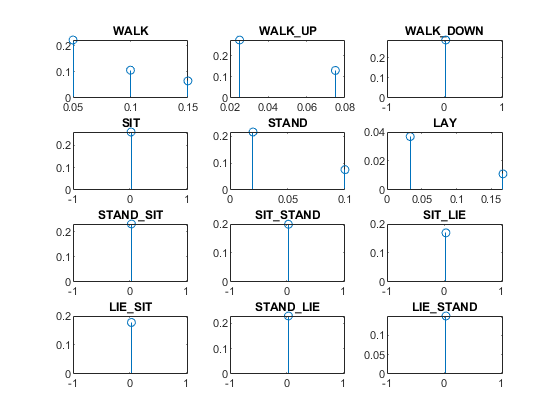

% region constants
X_AXIS = 1;
Y_AXIS = 2;
Z_AXIS = 3;
DATASETS_DIR = 'datasets';
LABELS_PATH = 'labels.txt';
COLORS = {'2f4f4f', '7f0000', '008000', '00008b', 'ff8c00', 'ffff00', '00ff00', '00ffff', 'ff00ff', '1e90ff', 'ffe4b5', 'fd4002'};
ACTIVITIES = ["WALK", "WALK\_UP", "WALK\_DOWN", "SIT", "STAND", "LAY", "STAND\_SIT", "SIT\_STAND", "SIT\_LIE", "LIE\_SIT", "STAND\_LIE", "LIE\_STAND"];
FS = 50;
THRESHOLD = 0.25;
% end region constants

labels = dlmread(LABELS_PATH, ' ');
datasets = load_datasets(DATASETS_DIR);

[num_act_ocurrences, acts_x, meaned_acts_x, freqs_x, dfts_x] = prepare_datasets(datasets, X_AXIS, FS, labels, ACTIVITIES);
[~, acts_y, meaned_acts_y, freqs_y, dfts_y] = prepare_datasets(datasets, Y_AXIS, FS, labels, ACTIVITIES);
[~, acts_z, meaned_acts_z, freqs_z, dfts_z] = prepare_datasets(datasets, Z_AXIS, FS, labels, ACTIVITIES);

plot_relevant_freqs(freqs_x, dfts_x, ACTIVITIES, THRESHOLD);

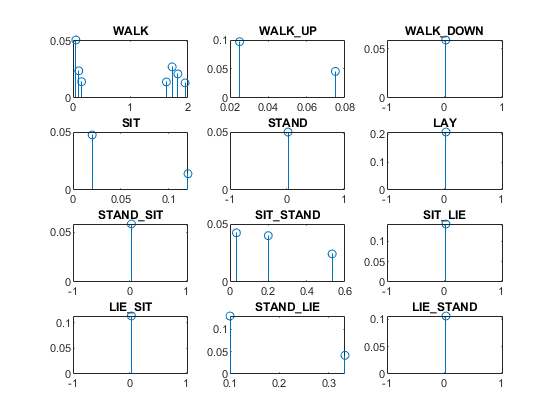

plot_relevant_freqs(freqs_y, dfts_y, ACTIVITIES, THRESHOLD);

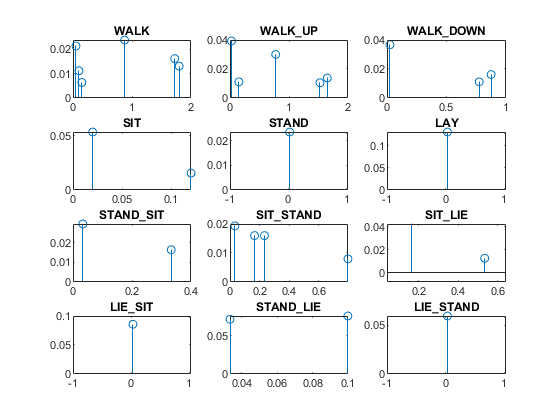

plot_relevant_freqs(freqs_z, dfts_z, ACTIVITIES, THRESHOLD);


%plot_dataset_param(meaned_acts_x, ACTIVITIES, @get_abs_slope, 'Absolute slope comparison - Axis X', COLORS);
%plot_dataset_param(meaned_acts_y, ACTIVITIES, @get_abs_slope, 'Absolute slope comparison - Axis Y', COLORS);
%plot_dataset_param(meaned_acts_z, ACTIVITIES, @get_abs_slope, 'Absolute slope comparison - Axis Z', COLORS);

%plot_dataset_param(meaned_acts_x, ACTIVITIES, @get_max_dist, 'Max. dist. comparison - Axis X', COLORS);
%plot_dataset_param(meaned_acts_y, ACTIVITIES, @get_max_dist, 'Max. dist. slope comparison - Axis Y', COLORS);
%plot_dataset_param(meaned_acts_z, ACTIVITIES, @get_max_dist, 'Max. dist. slope comparison - Axis Z', COLORS);

%plot_meaned_activities(acts_x, X_AXIS, ACTIVITIES);
%plot_meaned_activities(acts_y, Y_AXIS, ACTIVITIES);
%plot_meaned_activities(acts_z, Z_AXIS, ACTIVITIES);
%plot_meaned_dfts(freqs_x, dfts_x, num_act_ocurrences, ACTIVITIES, X_AXIS);
%plot_meaned_dfts(freqs_y, dfts_y, num_act_ocurrences, ACTIVITIES, Y_AXIS);%
%plot_meaned_dfts(freqs_z, dfts_z, num_act_ocurrences, ACTIVITIES, Z_AXIS);

%plot_activity(datasets, FS, COLORS, labels, ACTIVITIES, 1, 13); % (..., exp, activity)
%plot_datasets(datasets, FS, COLORS, labels, ACTIVITIES);
%plot_dfts(datasets, fs, labels);
%plot_windowed_dft(@hamming, FS, 'Janela de Hamming');
%plot_windowed_dft(@rectwin, FS, 'Janela retangular');
%plot_windowed_dft(@blackman, FS, 'Janela de Blackman');
%plot_windowed_dft(@hann, FS, 'Janela de Hann');